# **Final Project Submission - Mobile Robotics Spring 2025 (EECE 5550)**

# **Name of the Student : Varun Raghavendra**

## **Project Title : MATLAB Implementation of Fast Iterative Region Inflation for Computing Large 2D/3D Convex Regions of Obstacle-Free Space**

#### **Wang et al. ; Last revised ***18 Mar 2025, url = ***https://arxiv.org/abs/2403.02977**

## 1. Initialization

### 1.a. Importing Casadi 

close all; clear all; clc;
import casadi.*

### 1.b. Initialization of environment variables 

env_size = [50, 50];          
num_obstacles = 15;                   
bounding_box_size = 6;
min_spacing = 0.8;           
min_clearance = 2.0;

### 1.c Seed Ellipsoid Parameters

E0_center = [25; 25];         
w = 1.5; h = 0.75;            
E0_rot = pi/6;               
R = [cos(E0_rot), -sin(E0_rot); sin(E0_rot), cos(E0_rot)];

rect_local = 0.5 * [ -w -h; w -h; w h; -w h ];
Q = (R * rect_local')' + E0_center';
Q_hull = convhull(Q(:,1), Q(:,2));
P_seed = Q(Q_hull,:);

E0.L = R * diag([w/2, h/2]); 
E0.d = E0_center;   

## 2. Test Environment Setup [As explained in Section VII A in the paper]  

### 2.a Generate randomized obstacles in the environment, with flexibility to test different conditions and scenarios. 

function convex_obs = generate_obstacles(env_size, num_obs, min_spacing, Q, E0, min_dist, box)
    convex_obs = cell(num_obs,1);
    placed_centers = zeros(num_obs,2);
    Q_hull = convhull(Q(:,1), Q(:,2));
    Q_hull_pts = Q(Q_hull,:);
    
    % Generate ellipse points for collision checking
    theta_e = linspace(0, 2*pi, 100);
    ellipse_pts = (E0.L * [cos(theta_e); sin(theta_e)]) + E0.d;

    for i = 1:num_obs
        num_pts = randi([3,8]);
        is_valid = false;
        attempts = 0;
        
        while ~is_valid && attempts < 100
            center = [rand*(box(2,1)-box(1,1)) + box(1,1),...
                      rand*(box(2,2)-box(1,2)) + box(1,2)];
            attempts = attempts + 1;
            
            % Generate random convex polygon
            angles = linspace(0, 2*pi, num_pts+1)' + rand*pi/4;
            angles(end) = [];
            radii = rand(num_pts,1)*2 + 1;
            x_obs = center(1) + radii .* cos(angles);
            y_obs = center(2) + radii .* sin(angles);
            x_obs = min(max(x_obs,0), env_size(1));
            y_obs = min(max(y_obs,0), env_size(2));
            obs = [x_obs, y_obs];
            
            % Collision checks
            dist_to_Q = min(pdist2(obs, Q_hull_pts), [], 'all');
            dist_to_E = min(pdist2(obs, ellipse_pts'), [], 'all');
            existing_dists = vecnorm(placed_centers(1:i-1,:) - center, 2, 2);
            
            if (i == 1 || all(existing_dists > min_spacing)) && ...
               dist_to_Q > min_dist && dist_to_E > min_dist
                is_valid = true;
                convex_obs{i} = obs;
                placed_centers(i,:) = center;
            end
        end
    end
end

### 2.b Plot ellipse 

function h = draw_ellipse(L, d, color)
    theta = linspace(0, 2*pi, 100);
    circle = [cos(theta); sin(theta)];
    ellipse = L * circle + d;
    h = plot(ellipse(1,:), ellipse(2,:), '-', 'Color', color, 'LineWidth', 2);
end

### 2.c Make sure that there is no collision between the seed Q and the obstacle region O

function is_far = is_polygon_clear(obs, Q_hull_pts, ellipse_pts, min_dist)
    dists_to_Q = pdist2(obs, Q_hull_pts);
    dists_to_E = pdist2(obs, ellipse_pts');
    is_far = all(min(dists_to_Q,[],2) > min_dist) && all(min(dists_to_E,[],2) > min_dist);
end

### 2.d h2vrep [Halfspaces to Vertices Representation] 

function vertices = hrep2vrep(A, b)
    tol = 1e-6;
    m = size(A,1);
    pts = [];
    for i = 1:m-1
        for j = i+1:m
            M = [A(i,:); A(j,:)];
            if rank(M) < 2, continue; end
            x_int = M \ [b(i); b(j)];
            if all(A * x_int <= b + tol)
                pts = [pts; x_int'];
            end
        end
    end
    if ~isempty(pts)
        pts = unique(pts, 'rows');
        center = mean(pts,1);
        angles = atan2(pts(:,2)-center(2), pts(:,1)-center(1));
        [~, order] = sort(angles);
        vertices = pts(order,:);
    else
        vertices = [];
    end
end

### 2.e Plot Environment with initial seed parameters 

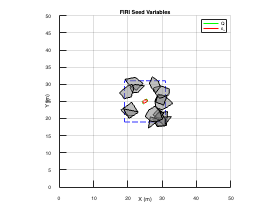

bounding_square = [E0_center(1)-bounding_box_size, E0_center(2)-bounding_box_size;
                   E0_center(1)+bounding_box_size, E0_center(2)+bounding_box_size];

convex_obstacles = generate_obstacles(env_size, num_obstacles,...
    min_spacing, Q, E0, min_clearance, bounding_square);

figure; hold on; grid on; axis equal;
xlim([0, env_size(1)]); ylim([0, env_size(2)]);
xlabel('X (m)'); ylabel('Y (m)');
title('FIRI Seed Variables');

% Plot bounding box
rectangle('Position', [bounding_square(1,1), bounding_square(1,2),...
    2*bounding_box_size, 2*bounding_box_size],...
    'EdgeColor', [0.2 0.2 1], 'LineStyle', '--', 'LineWidth', 1.5,...
    'HandleVisibility', 'off');

% Plot obstacles
for i = 1:numel(convex_obstacles)
    obs = convex_obstacles{i};
    if size(unique(obs, 'rows'), 1) >= 3
        k = convhull(obs(:,1), obs(:,2));
        fill(obs(k,1), obs(k,2), [0.5 0.5 0.5], 'FaceAlpha', 0.5,...
            'EdgeColor', 'k', 'HandleVisibility', 'off');
    end
end

% Plot seed elements
h_seed = plot(P_seed([1:end 1],1), P_seed([1:end 1],2), 'g-', 'LineWidth', 2);

% Draw initial ellipsoid (red)
h_initial = draw_ellipse(E0.L, E0.d, 'r');
valid_handles = [h_seed, h_initial];

legend(valid_handles, {'Q','ε₀'},...
    'Location', 'northeast');
hold off;

## 3. FIRI Main Functions [RsI and MVIE]

### 3.a FIRI Main Loop  

function [Pk, E_final, iter] = FIRI(seed_poly, obstacles, L0, d0, tol, max_iters)

    % Initialize
    E.L = L0;  
    E.d = d0;
    iter = 0;
    vol_prev = det(E.L);
    success_flag = true;
    Pk = struct('A', [], 'b', []);
    
    % Main loop
    while iter < max_iters && success_flag
        iter = iter + 1;
        
        % RsI Step: Generate obstacle-free polytope 
        [A, b] = RsI(E, obstacles, seed_poly);
        
        % Check for valid constraints
        if isempty(A) || isempty(b)
            warning('RsI failed. Using previous ellipsoid.');
            break;
        end
        Pk = struct('A', A, 'b', b);
        
        % Seed containment check 
        seed_pts = seed_poly'; % 2xN matrix
        seed_violation = any(A' * seed_pts > b + 1e-6, 1); % Check all seed points
        if any(seed_violation)
            warning('Seed containment violated at iteration %d', iter);
            success_flag = false;
            break;
        end
        
        % MVIE Step: Compute largest inscribed ellipsoid 
        [L_new, d_new, success] = MVIE_SOCP(Pk, E.L, E.d);
        if ~success
            warning('MVIE failed at iteration %d', iter);
            success_flag = false;
            break;
        end
        
        % Check ellipsoid containment in polytope
        ellipsoid_pts = L_new * [cos(0:0.1:2*pi); sin(0:0.1:2*pi)] + d_new; % 2xK
        ellipsoid_violation = any(A' * ellipsoid_pts > b + 1e-6, 1);
        if any(ellipsoid_violation)
            warning('Ellipsoid not contained in polytope at iteration %d', iter);
            success_flag = false;
            break;
        end
        
        % Update ellipsoid
        E_new.L = L_new;
        E_new.d = d_new;
        vol_new = det(L_new);
        
        % Convergence check
        if abs(vol_new - vol_prev)/vol_prev < tol
            E_final = E_new;
            break;
        end
        
        E = E_new;
        vol_prev = vol_new;
    end
    
    E_final = E;
end

### 3.b Restrictive Inflation (RsI) 

function [A, b] = RsI(E, obstacles, seed_poly)
    import casadi.*
    
    A_list = [];
    b_list = [];
    
    % Transform seed vertices to normalized ellipsoid space 
    Q_vertices = seed_poly'; % Original seed vertices (2xN)
    Q_bar = E.L \ (Q_vertices - E.d);
    
    for i = 1:length(obstacles)
        obs = obstacles{i};
        if size(obs, 1) < 3, continue; end
        
        % Transform obstacle vertices to normalized space 
        O_vertices = obs'; 
        O_bar = E.L \ (O_vertices - E.d); 
        
        % Solve min bᵀb in normalized space 
        opti = casadi.Opti();
        b_var = opti.variable(2, 1);
        opti.minimize(b_var' * b_var);
        
        % Seed containment: Q̄ ⊆ H(a) → vᵀb ≤ 1
        for col = 1:size(Q_bar, 2)
            v = Q_bar(:, col);
            opti.subject_to(v' * b_var <= 1);
        end
        
        % Obstacle exclusion
        for col = 1:size(O_bar, 2)
            u = O_bar(:, col);
            opti.subject_to(u' * b_var >= 1); 
        end
        
        % Solve and convert to original space
        opti.solver('ipopt', struct('ipopt', struct('print_level', 0)));
        try
            sol = opti.solve();
            b_opt = sol.value(b_var);
            norm_sq = b_opt' * b_opt + 1e-8;
            
            % Recover a_i and bi in normalized space
            a_i_normalized = b_opt / norm_sq; 
            bi_normalized = 1 / norm_sq;
            
            % Transform halfspace to original space
            a_i_original = (E.L' \ a_i_normalized)'; 
            bi_original = bi_normalized + a_i_original * E.d;
            
            A_list = [A_list, a_i_original'];
            b_list = [b_list; bi_original];
        catch
            warning('Obstacle %d: Optimization failed', i);
        end
    end
    
    % Fallback: Ensure at least seed-containing constraints
    if isempty(A_list)
        A_list = eye(2); 
        b_list = [1; 1] + A_list' * E.d; 
    end
    
    A = A_list;
    b = b_list;
end


### 3.c Maximum Volume Inscribed Ellipsoid (**MVIE**)

function [L_opt, bE_opt, success] = MVIE_SOCP(P, L_init, d_init)
    import casadi.*
    
    n = 2;                        % 2D 
    A_poly = P.A;                
    b_poly = P.b;                 
    m_constr = size(A_poly, 2);   % Number of halfspace constraints
    
    % Create CasADi Opti stack
    opti = casadi.Opti();
    
    %% Decision variables 
    LE = opti.variable(2, 2);     % Lower-triangular Cholesky factor LE
    L11 = LE(1, 1);               
    L21 = LE(2, 1);
    L22 = LE(2, 2);
    bE  = opti.variable(2, 1);    % Ellipsoid center 
    t   = opti.variable();        % Hypograph variable 
    
    %% maximize t 
    opti.minimize(-t);            % Equivalent to max t
    
    %% Constraints
    % 1) LE must be lower triangular with positive diagonal 
    opti.subject_to(LE(1, 2) == 0); 
    opti.subject_to(L11 >= 1e-8);   
    opti.subject_to(L22 >= 1e-8);
    
    % 2) Hypograph of geometric mean (34b): (diag(LE), t) ∈ K_{1/2}
    opti.subject_to(L11 * L22 >= t^2); 

    % 3) SOC constraints
    for i = 1:m_constr
        a_i = A_poly(:, i);       % Halfspace normal vector (2 x 1)
        b_i = b_poly(i);          % Halfspace offset
        
        % Paper: (bP - AP bE, AP LE) ∈ K3 (SOC constraint)
        % Implemented as: ||AP LE||_2 ≤ bP - AP bE
        linear_term = b_i - a_i' * bE;             
        vector_term = a_i' * LE;                    
        opti.subject_to(linear_term >= norm(vector_term')); 
    end
    
    %% Initialization
    LE_init = tril(L_init);       
    opti.set_initial(LE, LE_init);
    opti.set_initial(bE, d_init);
    opti.set_initial(t, sqrt(prod(diag(LE_init)))); 
    
    %% Solve with IPOPT 
    opts = struct('print_time', false, 'ipopt', struct('print_level', 0));
    opti.solver('ipopt', opts);
    
    try
        sol = opti.solve();
        L_opt = sol.value(LE);
        bE_opt = sol.value(bE);
        success = true;
    catch
        warning('Solver failed. Returning initial guess.');
        L_opt = LE_init;
        bE_opt = d_init;
        success = false;
    end
    
    % Ensure lower-triangular structure
    L_opt = tril(L_opt);
end

## 4. Run the algorithm and visualize the optimized free convex region  

### 4.a Run the FIRI Algorithm 

% Main script
[Pk, E_final, iter] = FIRI(P_seed, convex_obstacles, E0.L, E0.d, 1e-4, 15);


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |  43.00us (  3.31us)  40.37us (  3.11us)        13
       nlp_g  | 557.00us ( 42.85us)  94.33us (  7.26us)        13
  nlp_grad_f  |  68.00us (  4.86us)  47.25us (  3.38us)        14
  nlp_hess_l  |  43.00us (  3.58us)  40.54us (  3.38us)        12
   nlp_jac_g  |  81.00us (  5.79us)  80.12us (  5.72us)        14
       total  | 279.36ms (279.36ms) 214.24ms (214.24ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  | 354.00us ( 27.23us)  55.21us (  4.25us)        13
       nlp_g  |   2

disp(['FIRI converged in ' num2str(iter) ' iterations.']);

FIRI converged in 4 iterations.


### 4.b Visualize the optimized free convex region

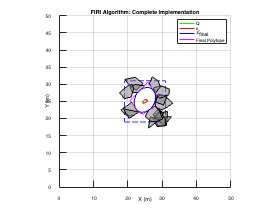


figure; hold on; grid on; axis equal;
xlim([0, env_size(1)]); ylim([0, env_size(2)]);
xlabel('X (m)'); ylabel('Y (m)');
title('FIRI Algorithm: Complete Implementation');

% Plot bounding box
rectangle('Position', [bounding_square(1,1), bounding_square(1,2),...
    2*bounding_box_size, 2*bounding_box_size],...
    'EdgeColor', [0.2 0.2 1], 'LineStyle', '--', 'LineWidth', 1.5,...
    'HandleVisibility', 'off');

% Plot obstacles
for i = 1:numel(convex_obstacles)
    obs = convex_obstacles{i};
    if size(unique(obs, 'rows'), 1) >= 3
        k = convhull(obs(:,1), obs(:,2));
        fill(obs(k,1), obs(k,2), [0.5 0.5 0.5], 'FaceAlpha', 0.5,...
            'EdgeColor', 'k', 'HandleVisibility', 'off');
    end
end

% Plot seed elements
h_seed = plot(P_seed([1:end 1],1), P_seed([1:end 1],2), 'g-', 'LineWidth', 2);

% Draw initial ellipsoid (red)
h_initial = draw_ellipse(E0.L, E0.d, 'r');

% Plot final results
h_final_poly = gobjects(1); 
if ~isempty(Pk)
    vertices = hrep2vrep(Pk.A', Pk.b);
    if ~isempty(vertices)
        k = convhull(vertices(:,1), vertices(:,2));
        h_final_poly = plot(vertices(k,1), vertices(k,2), 'm-',...
            'LineWidth', 2, 'DisplayName', 'Final Polytope');
    end
end

% Draw final ellipsoid (blue)
h_final_ellipse = draw_ellipse(E_final.L, E_final.d, 'b');

valid_handles = [h_seed, h_initial, h_final_ellipse];
if ~isempty(h_final_poly)
    valid_handles = [valid_handles, h_final_poly];
end

legend(valid_handles, {'Q','ε₀','ε_{final}', 'Final Polytope'},...
    'Location', 'northeast');
hold off;